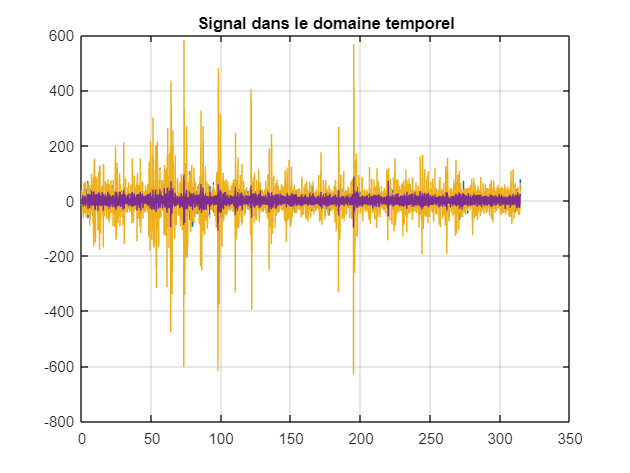

%% suppression de bruit, mouvements oculaires et signaux musculaires %%

eeg_data = csvread("data/Essai_1704_Test2.csv",1,0);
eeg_data1 = eeg_data(:,[1:8]); %toutes les électrodes
eeg_data2 = eeg_data(:,[1:4]); %électrodes 1,2,3,4

Fe = 250;
N = length(eeg_data2);
t = [0:N-1]/Fe;

figure(1)
plot(t,eeg_data2),grid
title('Signal dans le domaine temporel')

data = readmatrix("data/Essai_1704_Test2.csv");
data = data(:,1:8);

data =    -1.2200  -17.0750   37.8150   -9.7520  151.2960  -20.6220  -13.6600  -24.0770
   -3.7160  -19.3610   34.7090  -11.2190  144.7030  -21.6200  -12.9940  -24.7600
   -4.6990  -20.5370   32.2770  -11.6550  137.5240  -21.4970  -12.2910  -24.5350
   -4.2610  -20.5250   30.2860  -10.9070  129.4260  -20.1960  -11.3100  -23.2160
   -3.0880  -19.8980   28.0920   -9.3750  119.7580  -18.2570  -10.2700  -21.1760
   -1.8300  -19.3010   25.2830   -7.5920  108.1360  -16.3270   -9.4740  -18.8810
   -0.7800  -18.9510   22.1010   -5.8600   94.7340  -14.7190   -9.0680  -16.3810
    0.1380  -18.6560   19.2190   -4.2590   80.0980  -13.4670   -8.9540  -13.3050
    1.1580  -18.0860   17.2110   -2.8180   64.8950  -12.5770   -8.7870   -9.1540
    2.2620  -17.0570   16.1860   -1.6630   49.7560  -12.0970   -8.2030   -3.6060


fs = 250; %fréquence d'échantillonnage
signalDuration = size(data,1)/fs;
segmentDuration = 7;
totalSegments = 26;
% Objectif : prendre les signaux toutes les 5 secondes (5*250) pendant
% 7 secondes (7*250)
N = length(data);
nn = N/26;

for i = 1:25
    debut_sig = nn * i;
    startIndexCroix = int32(debut_sig);
    endIndexCroix = int32(debut_sig + 5*250);
    startIndexSignal = int32(endIndexCroix) ;
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:)
    segmentData = data(startIndexSignal:endIndexSignal, :)
    
end

croix =    29.8660   24.8770  101.0210   24.8640  191.6180   16.5550   25.2330   64.1750
   24.4820   20.8120   92.7030   19.5210  183.2380   14.1410   20.0960   62.5980
   19.2170   16.6360   83.2690   14.4490  172.6860   10.7940   14.5020   59.6660
   15.9730   14.4300   75.7410   11.6210  162.2770    8.5040   10.2290   57.3940
   16.1540   15.6290   72.4350   12.3200  154.0800    8.7390    8.7330   57.2830
   19.6560   19.9630   73.8060   16.2380  148.8820   11.5670   10.2860   59.6820
   24.7090   25.5100   78.3050   21.4320  145.8960   15.6870   13.7030   63.6770
   28.8490   29.8880   83.3820   25.4460  143.3620   19.2580   17.0190   67.5970
   30.3760   31.6570   86.9990   26.8280  139.6880   21.0410   18.7210   69.9770
   29.2640   31.0280   88.6760   25.8950  134.4060   21.2210   18.6700   70.3570


segmentData =    35.3850   21.3710   58.1560   20.3740   77.9960   28.9070   22.9900   90.5110
   33.7680   18.8900   54.8250   18.3700   77.8940   26.7600   21.6570   85.0090
   32.1620   15.9130   50.8890   15.7100   76.7370   23.5980   18.6370   79.1510
   30.8400   13.4520   46.8310   12.9590   75.3180   20.1530   14.4660   73.8550
   29.4030   11.9280   43.0030   10.2840   74.0240   16.8990    9.7100   69.8300
   27.1590   11.1620   39.8030    7.6070   72.9900   13.9800    4.9720   67.3690
   23.9150   10.8340   37.6810    5.0350   72.4420   11.4140    0.9020   66.5100
   20.1910   10.7580   36.8010    2.9140   72.5120    9.1690   -2.0730   67.0350
   16.8820   10.9930   36.9150    1.6110   72.9900    7.3010   -3.7620   68.4470
   14.9180   11.8700   37.6760    1.3990   73.5160    6.1780   -3.9380   70.2660


croix =    71.0780   48.9090  184.1610   23.8580  237.1940    8.6190   22.3320  168.2720
   67.9440   46.7800  181.1410   22.2790  231.0030    6.9030   21.6650  166.2620
   64.1770   45.0040  178.9690   21.7420  225.8820    6.7000   22.1580  165.4830
   60.1600   43.8810  177.5110   21.9960  222.0190    8.0080   23.8290  166.1400
   56.1890   43.3180  176.3340   22.3140  218.9370   10.0030   26.1180  167.7660
   52.2570   42.9460  174.9430   22.0240  215.7650   11.6980   28.1110  169.4460
   48.3140   42.4770  173.1250   21.0270  211.8860   12.5250   29.0780  170.4540
   44.4950   41.7930  170.9550   19.6430  207.2750   12.2990   28.6270  170.5810
   41.0290   40.8620  168.6240   18.0810  202.3900   11.1050   26.6000  169.9810
   37.8400   39.6180  166.2480   16.1640  197.8620    9.2800   22.9550  168.7920


segmentData =    12.6530    5.2360  -14.5360   15.4420  -32.2500    9.3420  -14.3580    9.5080
   10.5470    3.4370  -13.5430   14.6470  -36.1690    8.3810  -14.5400   10.1260
    9.6660    2.0410  -10.9600   14.2760  -38.7950    6.7000  -15.3290   11.3300
   10.0100    1.6160   -6.4250   14.6020  -39.1920    5.1250  -15.6510   13.3720
   10.8980    2.2650   -0.2920   15.5430  -37.5790    4.2120  -14.7260   16.0070
   11.6290    3.5600    6.6070   16.8400  -35.2850    4.1050  -12.4070   18.7180
   11.9500    4.7850   13.4960   18.2460  -33.8020    4.6120   -9.1310   21.0680
   12.1020    5.3960   19.8560   19.4670  -33.7780    5.3240   -5.7150   22.9000
   12.5210    5.3170   25.4160   20.2390  -34.6700    5.9710   -2.8610   24.5740
   13.3810    4.7370   29.9970   20.4480  -35.3000    6.6440   -0.8140   26.8930


croix =    31.7640   23.7690  149.0050   18.4240  124.1700   -2.0240   13.1930  144.3450
   29.7070   22.3220  148.5850   17.0650  125.8160   -2.7580   14.2370  141.8570
   28.6410   22.0410  148.7630   16.8750  128.9580   -2.6140   16.0280  139.6730
   28.4020   22.5160  148.7300   17.1570  132.4300   -1.7700   17.4940  137.1830
   28.5780   23.2620  147.8700   17.2030  135.4210   -0.4250   17.8330  133.9450
   28.5280   23.7900  145.8950   16.7150  137.6270    1.0540   16.8800  129.8420
   27.6110   23.6730  142.8160   15.7280  139.0630    2.2090   15.1950  125.0950
   25.5500   22.7480  138.9960   14.4280  139.9670    2.8310   13.8750  120.1820
   22.5960   21.2740  135.0260   13.1180  140.7480    3.0780   13.9480  115.6300
   19.3370   19.8210  131.4360   12.1700  141.8730    3.2660   15.8010  111.8270


segmentData =     2.7860    9.8800    8.7250   -1.4010    8.7650    0.1280    0.1960    1.3080
    3.2930   10.8270    9.9300   -0.6300   10.7670   -0.7360   -0.4270    0.6810
    2.4300   10.8820   10.2820   -0.5150   11.6830   -2.6490   -1.9860   -0.8300
    0.4530    9.7190    9.4090   -1.2680   10.9320   -5.7650   -4.3030   -3.3210
   -1.4120    7.9480    7.8720   -2.1880    9.2170   -9.1560   -6.5170   -6.0930
   -1.7470    6.6970    6.9540   -2.2480    8.1100  -11.3650   -7.6130   -8.0300
   -0.0340    6.7470    7.7860   -1.0000    8.9450  -11.3710   -7.0250   -8.3180
    2.9800    8.1130   10.5850    1.0900   11.9590   -9.2790   -5.0260   -6.8910
    6.0950   10.3540   14.6090    3.0920   16.3300   -6.1540   -2.5300   -4.3350
    8.7090   13.0200   18.7860    4.4210   21.0360   -3.0550   -0.3230   -1.3330


croix =    26.4790   40.1090  136.3890   11.7130  190.2770   -2.3710   39.6610  107.0520
   26.1460   40.7000  135.9570   11.2810  196.4810   -2.6070   40.8530  106.5380
   25.5650   41.9070  135.9530   10.8690  202.3680   -2.1790   40.9570  105.9350
   25.4670   43.5630  136.5750   10.6590  208.1090   -1.3330   39.6350  105.2710
   26.2060   45.1750  137.5420   10.7100  213.4290   -0.4830   36.9110  104.2220
   27.6540   46.1520  138.3650   11.1660  217.8130    0.0810   33.3240  102.4450
   29.5840   46.2780  138.8740   12.4260  221.1840    0.4450   30.0130  100.0890
   31.8420   45.7200  139.3150   14.7700  224.1360    0.9230   28.3750   97.7130
   34.2530   44.7640  139.9780   17.8850  227.4710    1.7440   29.3300   95.7110
   36.5780   43.6990  140.8310   20.9610  231.5800    2.9420   32.7920   94.0370


segmentData =   -70.9620  -54.6390 -235.8640  -29.3070 -189.6240  -11.4240  -96.1970 -178.3140
  -65.4220  -50.9450 -234.0390  -25.4460 -187.2330   -8.9790 -105.9810 -176.1360
  -60.8330  -49.1080 -231.8410  -23.8690 -186.6120   -8.7240 -112.9960 -175.2840
  -58.4110  -49.8010 -230.3250  -24.8490 -189.4610  -10.6780 -112.7390 -175.9480
  -58.2980  -52.5100 -230.1720  -27.4720 -195.7470  -14.1650 -103.1390 -177.5930
  -59.4590  -55.5980 -231.0510  -30.0090 -203.4110  -17.8620  -86.5920 -179.2900
  -60.3230  -56.9900 -231.5270  -30.7380 -209.3350  -20.1270  -68.8280 -179.9510
  -59.9150  -55.5590 -230.2200  -29.1750 -211.3820  -19.9490  -55.5490 -179.0670
  -58.7860  -52.3170 -227.4500  -26.8050 -210.3460  -17.9750  -49.6050 -177.6680
  -58.5930  -49.8460 -225.2180  -26.0590 -209.5740  -16.1560  -50.4070 -177.8300


croix =    62.6490   23.4330   79.4070   18.0970   98.7520    0.5540   25.9920   51.0770
   60.0600   21.1810   79.6630   17.0050  103.5630    0.6340   28.0250   48.8640
   57.6010   19.5640   78.9660   16.1520  107.8760    1.8000   29.6230   46.9860
   55.6890   19.0920   77.6420   15.8880  111.9860    3.6730   30.6350   45.4970
   54.1110   19.4660   75.7750   15.8980  115.7460    5.1840   30.8370   44.0900
   52.4380   19.9430   73.3000   15.4500  118.8400    5.2550   30.0330   42.3430
   50.7160   20.1180   70.5560   14.2270  121.4940    3.7820   28.4860   40.2930
   49.4490   20.2970   68.4010   12.6600  124.5700    1.8730   27.0510   38.5590
   48.7750   20.9390   67.4930   11.3260  128.7450    0.8820   26.5670   37.6470
   47.9780   21.8480   67.6440   10.3410  133.7390    1.1920   27.1460   37.3680


segmentData =    30.3380   30.4390  191.1210   11.7630  189.8390    0.3050   32.1970  168.3550
   29.1740   30.2000  185.5290   11.2350  186.8540   -0.0780   31.3300  165.5980
   27.3520   29.1780  179.0300   10.5750  183.9250   -0.3990   29.5120  162.8530
   25.0200   27.3820  172.6420    9.6950  181.8390   -0.6740   27.3810  160.3650
   22.4290   25.0050  167.2840    8.5880  181.2570   -1.0020   25.4430  158.6260
   20.1530   22.7220  163.7380    7.7000  182.6980   -1.1810   24.1710  158.3690
   18.9780   21.5060  162.4610    7.8400  186.4280   -0.8400   23.9920  160.1840
   19.5380   22.0710  163.3020    9.6080  192.1820    0.1600   25.1060  163.8860
   21.8180   24.2610  165.3830   12.7940  198.9540    1.5860   27.2780  168.1120
   24.7650   26.8570  167.2670   16.2410  205.1190    2.9530   29.7340  170.5500


croix =    23.8120   21.5290   12.4790   15.9270    3.5180    6.0800   40.4670  -15.5060
   23.1910   21.6090   12.5260   15.2350    7.2070    6.4170   39.7400  -14.2980
   21.1370   21.4350   12.4420   13.0940   11.0360    6.5020   37.1990  -14.0040
   18.3160   21.4730   12.8760   10.3810   15.2860    6.6360   33.6350  -13.4500
   15.6700   22.0050   14.2640    8.2580   20.0180    7.0990   30.1250  -11.5760
   13.9390   22.9530   16.6270    7.4560   24.8400    7.9820   27.4360   -7.9780
   13.3720   24.0610   19.6850    8.0470   29.0510    9.1570   25.7950   -3.0160
   13.7170   25.0520   22.9960    9.5640   31.9400   10.2350   24.9190    2.4460
   14.4750   25.6140   26.0630   11.3130   33.1250   10.7570   24.2310    7.4770
   15.3660   25.5900   28.6210   12.7940   32.8650   10.5960   23.2650   11.5270


segmentData =   -54.0000  -23.5050   -9.1700  -15.0570    9.2900  -12.3080  -19.0870   13.1790
  -52.2110  -22.6240   -7.2260  -14.2770   10.3310  -11.5610  -18.9350   16.2490
  -50.7900  -22.1450   -5.9570  -13.7350   10.8270  -11.1240  -19.2580   18.9410
  -49.3560  -21.6870   -5.0750  -13.2230   11.1900  -11.0700  -19.6190   21.4010
  -47.6970  -20.9900   -4.1850  -12.5470   11.7990  -11.4080  -19.7440   23.8570
  -45.7000  -19.8680   -2.7550  -11.4000   13.1310  -11.8520  -19.3340   26.7480
  -43.2670  -18.1500   -0.2990   -9.5000   15.5330  -11.9710  -18.0660   30.5000
  -40.5280  -15.8800    3.3350   -6.9530   18.8800  -11.6230  -15.8660   35.1290
  -38.0500  -13.4720    7.8380   -4.4380   22.6070  -11.0970  -13.0000   40.0960
  -36.5270  -11.5440   12.5800   -2.8680   26.0670  -10.8150   -9.8670   44.6090


croix =    13.6950    6.8170   56.2280    9.3300   76.8210    3.0700    7.6540   77.9120
   14.6310    7.9940   58.3330   10.6860   80.8030    4.5670    6.5360   83.1010
   17.1540   10.2000   61.3110   12.2530   86.0990    7.2930    7.1630   89.3680
   21.4070   13.5700   64.9350   14.1300   91.9470   10.7490    9.0300   96.2650
   27.1700   17.8570   68.7450   16.3810   97.3270   14.1820   11.4100  102.8510
   33.9120   22.5620   72.4770   18.9100  101.5690   16.9210   13.7790  108.2230
   40.6270   26.9100   76.1450   21.3160  104.4620   18.4850   15.7730  111.8090
   46.0820   30.0100   79.8130   23.1780  106.0630   18.8000   17.1790  113.5420
   49.4060   31.2620   83.4200   24.3430  106.6120   18.3210   18.0380  113.8190
   50.4300   30.7390   86.6590   24.8040  106.5160   17.7230   18.4830  113.1140


segmentData =    22.7610   22.9090   61.0270    4.9920   49.2610   -3.4630   17.4070  113.5920
   22.4740   23.0530   60.7200    5.1610   49.8290   -3.5490   15.2410  112.0820
   21.8010   22.4890   61.3170    5.2340   50.9320   -3.8990   13.9250  110.5830
   20.6600   21.4600   62.7230    5.1930   52.2710   -4.6980   14.0570  109.1280
   18.9570   20.2740   64.5400    5.0400   53.3570   -5.9790   16.0590  107.6900
   16.8560   19.1430   66.1610    4.8430   53.7150   -7.5640   19.9200  106.0860
   14.7950   18.1060   67.0730    4.6990   53.1230   -9.2020   25.0120  104.0540
   13.2060   17.0790   67.1610    4.6680   51.7590  -10.6780   30.2450  101.4780
   12.4500   16.1640   66.9270    4.8950   50.2450  -11.6700   34.6180   98.6740
   12.7720   15.7300   67.1470    5.5600   49.3960  -11.7760   37.5390   96.1660


croix =    23.3960   21.6760   95.2010    9.0180   53.2430    3.9880    5.0310  111.3930
   22.0510   22.7930   98.8360    9.5240   53.4470    3.8840    5.3160  113.3000
   20.4570   23.5880  101.5310    9.9930   54.5270    3.8530    6.6450  114.8500
   19.1740   24.2850  102.9780   10.6150   55.9400    4.3990    9.7850  116.2470
   17.9720   24.7840  103.0050   11.2900   57.0360    5.4430   14.4970  117.4930
   16.1530   24.5640  101.6990   11.6640   57.4560    6.2130   19.4900  118.4030
   13.4800   23.1790   99.3700   11.4260   57.2960    5.8650   23.0280  118.7450
   10.6890   20.8670   96.4190   10.5560   56.9660    4.2640   23.8950  118.3790
    9.0460   18.5320   93.3880    9.4390   57.0170    2.1090   22.0850  117.5360
    9.3800   17.0660   90.8700    8.6800   57.9170    0.3600   18.5610  116.8400


segmentData =   -34.4690  -32.3990  -42.5470   -9.9910   44.2860  -29.0210  -32.9720  -58.3040
  -35.6920  -34.0860  -44.6620   -9.7470   42.4640  -29.2720  -34.2360  -57.7770
  -37.2380  -35.7760  -47.6480  -10.6930   39.2120  -30.0740  -36.7060  -58.7280
  -39.0070  -37.1010  -51.1940  -12.5270   35.5140  -30.8820  -39.4270  -60.8820
  -41.0570  -38.1480  -55.0300  -14.8690   32.1940  -31.5940  -41.4810  -63.8600
  -43.1760  -39.1000  -58.7390  -17.1640   29.6960  -32.1320  -41.9340  -67.0950
  -44.6210  -39.8030  -61.7540  -18.6760   28.0640  -32.1780  -39.9600  -69.9310
  -44.5120  -39.7990  -63.6880  -18.7480   27.0130  -31.4450  -35.4400  -71.9850
  -42.5390  -38.8160  -64.6150  -17.1470   26.0210  -30.0590  -29.3970  -73.3140
  -39.3390  -37.1600  -65.0710  -14.2990   24.4070  -28.5910  -23.6810  -74.3090


croix =    17.4430    6.1730   36.8960    9.7990   56.3870   19.6830    2.9000   66.2000
   17.8370    5.8830   34.7070    9.6420   58.3650   20.0930    5.8340   64.8210
   19.8350    6.4040   33.8630    9.8440   60.9840   20.6580    7.8840   63.1320
   23.0220    7.7050   34.0900   10.5640   64.2190   21.1760    9.2680   61.1870
   26.4070    9.3280   34.7840   11.6760   67.5210   21.4950    9.9230   58.9260
   28.8110   10.4600   35.1030   12.6150   69.7640   21.3390    9.3570   56.0460
   29.5100   10.4410   34.3420   12.7580   69.8620   20.4380    7.0880   52.2350
   28.5550    9.1620   32.3420   11.9290   67.5090   18.7990    3.2640   47.4460
   26.3700    6.9310   29.4860   10.3780   63.3810   16.6630   -1.2300   41.9260
   23.5010    4.3710   26.5730    8.5720   58.9400   14.4420   -5.0970   36.2540


segmentData =     4.9410   -0.4960   34.7790  -13.0040  121.4150   -4.4710  -10.8850   -2.7230
    2.4670    1.1020   34.8430  -13.0960  122.5200   -2.8790   -8.7570   -2.6430
    1.2450    3.5990   36.0050  -12.4880  124.4420   -1.6890   -4.9580   -2.0820
    1.7650    6.1760   37.6950  -11.1930  126.4200   -1.0300   -0.4740   -1.5920
    3.9810    8.2250   39.1890   -9.5380  127.6420   -0.6570    3.6460   -1.6780
    7.2290    9.5270   39.9390   -7.9240  127.6810   -0.2170    6.7180   -2.5260
   10.3870   10.1330   39.7710   -6.6870  126.5500    0.3820    8.3770   -4.0130
   12.3100   10.1470   38.7600   -6.1080  124.3620    0.7930    8.3240   -6.0030
   12.3440    9.5760   37.0460   -6.3360  121.0700    0.4210    6.3990   -8.4920
   10.5940    8.3430   34.8750   -7.2110  116.6410   -1.1050    2.8520  -11.3450


croix =   -16.6700  -22.9200  -65.1040  -13.5700  -64.4940  -10.0890   -5.3550 -100.2140
  -18.5020  -23.2260  -68.4390  -15.5330  -67.4090   -9.9570   -9.1040 -103.9680
  -18.5520  -22.1230  -70.8900  -16.2970  -70.4490   -7.9770  -11.5820 -106.7150
  -16.7570  -20.2390  -72.1840  -15.7160  -73.9850   -4.6780  -12.5790 -108.4590
  -14.0990  -18.8200  -72.9950  -14.4420  -78.7730   -1.5280  -12.7680 -109.8570
  -11.7600  -18.7640  -74.2030  -13.2950  -85.0790    0.0930  -12.9830 -111.5670
  -10.3340  -19.9490  -76.3870  -12.6630  -92.3120   -0.2500  -13.6200 -113.7750
   -9.8020  -21.6280  -79.7630  -12.5450  -99.5170   -2.0600  -14.7080 -116.2540
  -10.1090  -23.4060  -84.3010  -12.9520 -106.1100   -4.5050  -16.2680 -118.7320
  -11.5160  -25.5900  -89.8800  -14.0500 -112.2370   -6.9170  -18.4280 -121.2190


segmentData =   -12.1400  -10.6420   -9.6750   -5.3090   11.6840  -11.2930   15.4050  -26.7300
   -8.6780   -9.4140  -10.2870   -3.1150   15.4170  -10.4370   12.9730  -27.8680
   -6.3690   -8.8540  -11.4640   -1.3770   18.4420  -10.2800   10.7410  -29.2880
   -5.2850   -8.8200  -12.5190   -0.2830   21.0540  -10.7740    9.3070  -30.7290
   -5.3610   -9.0290  -13.2050    0.0270   23.5400  -11.5340    8.8850  -32.1670
   -6.4150   -9.1660  -13.7100   -0.5040   25.9920  -12.0990    9.1870  -33.8840
   -7.9130   -9.0280  -14.2460   -1.6100   28.3200  -12.1120    9.8280  -36.1800
   -9.0510   -8.5820  -14.8020   -2.6790   30.3260  -11.4710   10.6750  -39.0340
   -9.1530   -7.7560  -15.0470   -2.9360   31.9140  -10.1780   11.9030  -41.9670
   -8.0870   -6.3590  -14.5300   -1.8520   33.1360   -8.2950   13.6650  -44.3490


croix =   -13.4070   -7.1350  -18.9470   -8.8370   10.6800   -5.1810   -9.6050  -28.5780
  -12.5900   -6.1800  -16.9590   -8.8860    9.7790   -4.1350   -7.0250  -26.1990
  -11.9740   -5.7930  -15.6050   -9.0450    7.4650   -3.5890   -5.7050  -24.3620
  -11.1520   -5.4060  -14.7300   -8.8590    4.4260   -3.5570   -5.6880  -22.5970
  -10.1060   -4.8960  -14.4660   -8.4400    1.2890   -4.0720   -7.0590  -20.6820
   -9.0040   -4.4680  -14.9000   -8.0470   -1.5040   -5.0450   -9.7110  -18.7350
   -7.8010   -4.0790  -15.5560   -7.5800   -3.4080   -6.1000  -13.0480  -16.9130
   -6.3170   -3.3000  -15.4750   -6.6060   -3.7280   -6.6360  -16.0260  -15.1050
   -4.6750   -1.8420  -14.0820   -4.8930   -2.2350   -6.2090  -17.6660  -13.1360
   -3.4390   -0.0060  -11.9240   -2.8400    0.3310   -4.9360  -17.5780  -11.1980


segmentData =     1.4390   -4.7740    3.6590   -1.1450   81.4810   -8.4060  -10.9520  -19.3100
    3.4930   -3.4770    3.9160    0.5480   77.2760   -8.5050  -11.1230  -19.4980
    5.6110   -1.8620    4.5620    2.2240   73.4610   -8.6850  -11.7970  -19.3240
    6.7580   -0.6950    5.1260    3.3830   69.9450   -8.9430  -13.2010  -19.1920
    6.4720   -0.5360    4.9810    3.6830   66.3430   -9.2540  -15.2240  -19.6000
    5.1650   -1.3990    3.7980    3.2390   62.3050   -9.5660  -17.4120  -20.6730
    3.8610   -2.6660    2.0130    2.6750   57.9210   -9.6570  -19.0700  -21.8570
    3.4010   -3.5150    0.6450    2.5960   53.6800   -9.0990  -19.4980  -22.2530
    3.8500   -3.4320    0.6180    3.1100   50.0960   -7.5300  -18.3710  -21.1880
    4.5750   -2.3740    2.1840    3.9410   47.4120   -5.0440  -16.0110  -18.6060


croix =     2.7190    6.0760   -5.8460    4.0810   10.5470   -1.6840   -2.5540  -20.2810
    3.4310    5.7480   -8.2870    4.3720    7.3050   -1.3210   -5.6140  -19.4540
    3.6160    5.4030  -11.2590    3.7140    3.9480   -0.5500   -8.5120  -19.0420
    2.8590    4.9150  -14.8910    1.8800    0.3460    0.1770  -11.1150  -19.4720
    1.1930    4.3280  -18.8510   -0.7570   -3.3820    0.4670  -13.2500  -20.8010
   -0.9670    3.6830  -22.5530   -3.4280   -6.9590    0.1810  -14.7230  -22.6710
   -2.8410    3.1900  -25.2760   -5.1970   -9.9900   -0.4690  -15.1980  -24.3830
   -3.7500    3.1020  -26.5670   -5.4730  -12.2420   -1.2280  -14.3830  -25.3680
   -3.6450    3.3680  -26.7200   -4.4460  -13.9020   -2.0460  -12.3810  -25.5910
   -3.1630    3.5130  -26.8010   -2.9930  -15.4900   -3.0400   -9.8270  -25.5640


segmentData =   -10.1340  -10.5710  -43.2030   -5.0740  -50.9100    0.5810   -4.0520 -119.6860
  -10.2490   -9.8230  -40.7600   -3.5030  -51.7660    0.7300    0.2000 -114.9540
  -10.1640   -8.6330  -37.7450   -2.1990  -51.9820    0.8420    4.3000 -109.2180
   -9.3530   -6.7870  -34.7300   -1.2760  -51.8950    1.1140    7.7850 -103.4570
   -7.7950   -4.6970  -32.3690   -0.8050  -52.1870    1.4550   10.2110  -98.6770
   -6.0130   -3.2120  -31.0520   -0.8670  -53.5520    1.4880   11.1670  -95.5990
   -4.6460   -2.9550  -30.6990   -1.4870  -56.2420    0.8840   10.4400  -94.4250
   -4.1130   -3.9820  -31.0510   -2.5860  -59.9280   -0.4110    8.1670  -94.8880
   -4.4920   -5.9160  -31.9720   -3.9550  -63.8620   -2.1810    4.8580  -96.4730
   -5.3730   -8.0140  -33.2960   -5.1980  -67.1880   -3.9900    1.3180  -98.6170


croix =    -9.0300   -9.6780   -1.5070  -15.4240    7.1260   -7.2880  -12.2040   14.2160
   -9.2240   -8.6700   -2.8340  -16.0980    7.8180   -7.8150  -11.2400   14.1380
   -8.1650   -6.7770   -2.8920  -15.1480    9.1540   -7.9360   -8.9810   13.6300
   -5.9660   -4.7780   -2.1730  -12.7960   10.4820   -7.8670   -6.1680   12.3530
   -3.2180   -3.2870   -1.4460   -9.9240   11.0540   -7.8490   -3.8200   10.0000
   -0.9320   -2.7630   -1.5850   -7.6950   10.0670   -8.0930   -2.8840    6.3110
   -0.0780   -3.4880   -3.1430   -6.7950    6.9490   -8.6480   -3.7560    1.3280
   -0.9230   -5.2960   -5.9190   -7.0340    1.8310   -9.2860   -6.0490   -4.3190
   -2.9820   -7.6060   -9.0720   -7.7520   -4.4470   -9.6880   -8.9510   -9.6510
   -5.6120   -9.8460  -11.7710   -8.5090  -10.8620   -9.7820  -11.7910  -13.9730


segmentData =    -4.4800  -13.5500  -57.3270   -5.3110  -86.0340  -14.0290  -16.2190  -47.2000
   -6.0160  -13.8980  -59.3980   -8.2730  -87.7360  -14.3530  -14.6130  -46.8330
   -5.8330  -13.0100  -60.5370   -9.9860  -89.0140  -14.2740  -12.6300  -46.8610
   -4.7840  -11.1560  -60.7820  -10.2940  -90.0010  -13.6100  -11.2040  -47.1280
   -3.6450   -8.9750  -60.7040   -9.5350  -90.9510  -12.2180  -11.0430  -47.4900
   -3.0890   -7.3120  -61.0250   -8.4410  -92.2160  -10.3150  -12.3160  -47.9670
   -3.6420   -6.8120  -62.1400   -7.7650  -94.0230   -8.5420  -14.5890  -48.7130
   -5.5920   -7.6420  -63.9100   -7.9210  -96.2750   -7.5830  -17.0470  -49.8860
   -8.8140   -9.3890  -65.7600   -8.7900  -98.4850   -7.5420  -18.8180  -51.4620
  -12.7080  -11.2360  -67.0670   -9.8990 -100.0230   -7.7930  -19.3290  -53.1750


croix =    -3.2350   -2.1840   -2.2510   -0.1100  -13.1260   -9.0730   10.7960    3.1870
   -3.9380   -3.1560   -4.0780   -0.4340  -14.7780   -8.1020    9.0710   -2.8710
   -3.7630   -2.6620   -4.6390    0.8060  -15.4350   -6.3370    7.9320   -7.8800
   -2.9650   -1.3000   -4.1240    3.0910  -14.8140   -4.3140    7.6420  -11.9990
   -2.1430   -0.1010   -3.2040    5.3520  -13.2630   -2.9240    7.5850  -15.9480
   -1.6840    0.2350   -2.4720    6.7820  -11.1010   -2.7530    7.0960  -20.2650
   -1.2820   -0.0910   -1.9120    7.3700   -8.0910   -3.5580    6.3660  -24.7410
   -0.4830   -0.5620   -1.2540    7.4670   -3.9930   -4.6470    6.1550  -28.8260
    0.6150   -1.1460   -0.6110    7.2570    0.7040   -5.6030    6.8520  -32.2640
    1.4010   -2.2220   -0.5110    6.7820    4.9740   -6.4640    8.0600  -35.2390


segmentData =   -10.4780  -15.4990  -58.9080   -8.7230  -30.3810  -14.1120  -11.0890  -80.7750
   -9.0710  -16.2520  -60.4430   -9.7310  -31.7120  -13.9900  -12.2270  -83.4020
   -7.5460  -16.7230  -62.0270  -10.1850  -32.6910  -12.8710  -12.3720  -86.3230
   -6.0960  -16.8660  -63.3090  -10.0030  -32.7270  -11.0690  -11.4960  -88.8340
   -5.0500  -16.9160  -63.9320   -9.4390  -31.7190   -9.2320   -9.7870  -90.4420
   -4.5030  -17.1590  -63.6640   -8.7750  -30.0970   -7.9640   -7.6360  -91.1270
   -4.2440  -17.8520  -62.8180   -8.2040  -28.9120   -7.7140   -5.8520  -91.5680
   -4.1910  -19.3560  -62.3420   -7.9720  -29.6390   -8.8830   -5.5150  -92.8540
   -4.6550  -21.9460  -63.1070   -8.3550  -33.3490  -11.6160   -7.1710  -95.5690
   -5.9060  -25.2650  -65.0910   -9.3770  -39.8450  -15.4130  -10.2730  -99.1290


croix =   -16.0700   -9.6770  -56.1890   -3.9280  -62.4790   -3.6050  -25.8600  -37.2380
  -17.8650  -10.0780  -54.0460   -5.2430  -62.5330   -3.4160  -22.9070  -33.5120
  -19.2230   -9.7590  -51.9260   -5.9630  -61.8370   -3.1400  -20.1050  -29.5730
  -19.7840   -8.5910  -50.4190   -6.0190  -61.3370   -2.5450  -17.8540  -26.2430
  -19.6630   -6.8150  -49.8100   -5.8460  -61.6040   -1.8370  -16.3360  -24.2900
  -19.0590   -4.9710  -49.7600   -5.9350  -62.4500   -1.4900  -15.3600  -23.9520
  -18.1350   -3.6280  -49.7120   -6.4600  -63.2770   -1.8870  -14.5810  -24.8890
  -17.1000   -2.9140  -49.2780   -7.0850  -63.4020   -2.9490  -13.6870  -26.2630
  -16.3260   -2.5830  -48.5800   -7.3710  -62.4600   -4.2000  -12.5620  -27.2280
  -16.3610   -2.5310  -48.4660   -7.4000  -60.8820   -5.2250  -11.4870  -27.6020


segmentData =    14.4040    1.5320   20.0070   13.0230   80.0140   16.1690   12.8310   70.9500
   14.6120    1.5050   18.4650   11.4570   78.7410   16.0200   12.2350   68.7960
   14.2170    0.4180   16.1030    8.8730   76.0400   14.8250   10.3690   64.5930
   13.9180   -1.2450   13.2530    6.1240   72.5660   13.0040    7.7990   59.1460
   14.6900   -2.3690   10.9510    4.3770   69.4770   11.4690    5.6060   53.7840
   17.1570   -1.9620   10.2890    4.3560   67.7740   10.9600    4.7120   49.5780
   21.1130    0.1750   11.6250    5.9580   67.7080   11.5790    5.3850   46.7540
   25.5290    3.2630   14.2620    8.3330   68.6350   12.7680    7.0300   44.6930
   29.1270    6.0160   16.9400   10.3010   69.5390   13.6500    8.5030   42.5140
   31.1450    7.4880   18.6810   10.9470   69.7860   13.5970    8.8550   39.6930


croix =     3.7210   -0.0600  -12.5980    3.5070    4.6560    0.3320  -14.4540  -20.2260
    3.7560    0.9830  -13.7620    3.8780    3.4870    1.2020  -15.1000  -21.5080
    3.1410    1.4380  -16.4500    2.7370    1.7200    1.7230  -15.8260  -23.3510
    2.1590    1.2880  -20.2040    0.4570   -0.7150    2.0000  -16.8360  -25.5920
    1.2260    0.8780  -24.3650   -2.0820   -3.8540    2.2650  -18.4110  -28.1270
    0.5730    0.5550  -28.4150   -4.0670   -7.8460    2.7360  -20.8730  -30.9110
    0.1120    0.2880  -32.2890   -5.2600  -13.0130    3.3520  -24.4930  -33.9480
   -0.3630   -0.1980  -36.3180   -5.9280  -19.6120    3.7750  -29.2520  -37.1910
   -0.9040   -0.8730  -40.7160   -6.2840  -27.3540    3.7990  -34.5180  -40.2570
   -1.2560   -1.1810  -45.1690   -6.1520  -35.3000    3.6330  -39.0610  -42.4170


segmentData =    15.1120    9.1670   22.3100   10.8930    0.2970    2.1820    7.2440   47.1820
   12.9410    6.2250   22.3440   10.4280   -1.7100   -0.4550    5.3540   45.6240
   10.7280    3.8480   24.4520   10.0240   -1.6690   -2.5950    4.4650   44.6650
    9.3300    2.6580   28.7140    9.7500    0.5580   -3.9380    4.6610   44.2620
    8.9810    2.5540   34.4870    9.6250    4.1910   -4.6690    5.5580   44.1160
    9.4130    2.9170   40.9240    9.7540    8.1410   -4.9430    6.8540   44.0650
   10.2770    3.2020   47.4410   10.2680   11.6410   -4.6970    8.7170   44.2530
   11.4320    3.3890   53.9560   11.2280   14.5950   -3.8980   11.5880   45.1270
   12.8400    3.8280   60.6910   12.6210   17.4170   -2.7110   15.6800   47.2460
   14.1110    4.6240   67.5200   14.1820   20.4470   -1.5030   20.5210   50.7550


croix =     6.2580   -3.5800  -10.0840    4.2700    8.6970    3.6820   -4.4150   23.6090
    5.7100   -3.8790   -9.2890    3.6200    7.3360    2.8750   -5.6080   21.0200
    5.2110   -3.8680   -8.4290    2.9320    6.8670    1.9520   -6.9650   19.1970
    4.9370   -3.2370   -7.6710    2.3110    7.0200    1.2060   -8.3190   18.2050
    5.1180   -1.7150   -6.8270    1.8560    7.5500    0.7990   -9.3700   18.0870
    6.0530    0.8200   -5.2960    1.8750    8.6170    0.9260   -9.5880   19.0300
    7.9150    4.1680   -2.5850    2.7630   10.4710    1.7830   -8.5410   21.2010
   10.3920    7.6420    0.9590    4.5320   12.7600    3.1690   -6.4910   24.2660
   12.6940   10.3130    4.0880    6.5650   14.4500    4.2900   -4.5490   27.2630
   14.0780   11.5960    5.5950    8.0210   14.6560    4.3190   -3.9860   29.2780


segmentData =     3.4430    4.0000   32.8680    1.9200   44.0860   -8.0240    2.2720    0.2700
    2.3650    4.3840   31.5380    0.6960   45.2300   -6.9120    3.1990    0.4620
    0.4710    4.6460   30.5970   -0.6520   46.8200   -5.5310    4.3720    1.0000
   -2.2630    4.4510   29.5960   -2.0920   48.5360   -4.3790    5.1180    1.5880
   -5.3840    3.7180   27.9940   -3.3690   50.1770   -3.7510    5.0310    1.9070
   -7.8830    2.9730   25.8450   -3.9310   51.9220   -3.3980    4.3960    2.1390
   -8.7950    2.9500   23.8300   -3.4580   53.9820   -2.8250    3.9030    2.7900
   -7.9060    3.8950   22.6850   -2.3430   56.2060   -1.8360    4.0290    4.1250
   -5.6970    5.5740   22.8930   -1.2580   58.3280   -0.5260    4.8700    6.0640
   -2.9830    7.5380   24.4930   -0.5690   60.1750    0.8500    6.1880    8.2330


croix =    -5.8700   -8.2740  -31.1410   -5.6440  -33.4080  -12.1150   -6.4840  -49.1940
   -7.0320   -8.9580  -32.1550   -5.2470  -33.6300  -12.8900   -7.5020  -48.4450
   -8.2400   -9.4700  -33.4660   -5.1610  -34.2670  -13.5750   -8.0900  -47.3480
   -8.7420   -9.4880  -34.2250   -4.9750  -34.8600  -14.0210   -8.1600  -45.6070
   -8.3840   -8.9170  -33.8460   -4.5310  -34.8380  -14.0250   -7.8370  -43.0820
   -7.6980   -8.0590  -32.3490   -4.0420  -33.9600  -13.4960   -7.3400  -40.0480
   -7.3810   -7.4080  -30.2820   -3.8520  -32.4450  -12.5050   -6.7990  -37.0990
   -7.6550   -7.1420  -28.3400   -4.0850  -30.7330  -11.2620   -6.2810  -34.7850
   -8.2810   -7.0390  -27.1120   -4.6440  -29.3670  -10.1170   -6.0130  -33.4000
   -8.9000   -6.8100  -26.9030   -5.3450  -28.8800   -9.4490   -6.3060  -32.9500


segmentData =    10.3220    9.9330    5.1050    7.0340  -55.0160   21.0080   12.8530   41.4510
   10.5730   11.1490    4.5740    7.3830  -54.2070   20.9440   11.1960   38.6220
   11.4380   11.6810    3.9770    8.0140  -54.5930   20.8950    9.3860   35.7540
   12.6810   11.4640    3.6780    8.4970  -55.1080   20.6830    7.4000   32.9200
   13.6010   10.5010    3.7830    8.4690  -54.8390   20.0450    5.2050   30.2750
   13.4250    8.8740    4.1860    7.7510  -53.4040   18.9350    3.0910   28.0330
   11.8130    6.8070    4.8220    6.5220  -50.9150   17.6460    1.7660   26.4670
    9.1250    4.6170    5.6620    5.1940  -47.8510   16.4170    1.9610   25.7470
    6.2660    2.6360    6.5870    4.0480  -44.8550   15.1360    3.9500   25.8040
    4.1870    1.1000    7.3990    3.1220  -42.4730   13.5020    7.3710   26.3890


croix =    11.5720   12.8610   58.9990   15.6360   79.8790    0.3590    6.4420   62.3200
   11.4650   13.2470   59.7200   16.3640   81.1150   -0.7670    6.6080   61.1920
   10.3340   12.3550   58.6040   15.7990   81.1590   -2.6210    5.5650   58.7090
    8.5220   10.5840   56.1420   14.2150   80.0730   -4.5500    3.0790   55.6030
    6.9370    8.8050   53.4540   12.3090   78.4970   -5.8930   -0.3030   52.8370
    6.4700    7.8890   51.6180   10.8680   77.0750   -6.3010   -3.5090   50.9790
    7.1560    7.9650   50.8360   10.1280   75.7640   -6.0450   -5.7900   49.6540
    8.1110    8.2610   50.2950    9.6220   73.9440   -5.8360   -7.1960   47.7620
    8.5040    7.9130   49.0440    8.8020   71.2720   -6.1070   -8.1160   44.5000
    8.2860    6.7090   46.8680    7.5900   68.1400   -6.5860   -8.7250   40.1000


segmentData =    21.4010   13.9180   63.2840    9.5270  100.8600   13.8630   -1.7050  113.2550
   21.4300   13.3150   60.9600    8.7580   99.4300   13.4320   -2.9330  111.9550
   21.3300   12.8710   59.1650    8.9030   97.6230   13.4290   -2.6120  110.8210
   20.4470   11.8510   57.2480    9.3120   95.4910   13.1830   -1.5390  109.1310
   18.3910    9.8600   54.7830    9.3290   93.0510   12.5060   -0.5450  106.2030
   15.5520    7.2770   51.9110    8.7930   90.6920   11.8300   -0.0770  102.0580
   12.7430    4.8130   48.8990    7.8560   88.8290   11.5460   -0.2790   97.2470
   10.5100    2.8530   45.6850    6.6640   87.4350   11.4750   -1.1830   92.2130
    9.0400    1.4080   42.0690    5.4210   86.1720   11.1750   -2.5880   87.1300
    8.4210    0.4400   38.1830    4.5220   84.8720   10.5350   -3.9340   82.1960


croix =    -7.1720   -5.7840  -50.2180   -1.1260  -88.9420    3.2920   36.2660  -62.0050
   -3.7890   -2.8420  -40.1490    1.8520  -85.1900    5.4370   39.6290  -53.4770
    0.3040    0.2060  -30.8110    5.6700  -81.0130    8.1510   41.6730  -43.9540
    4.0950    2.8060  -22.9090    9.5490  -76.2860   11.0040   42.7620  -33.8770
    6.7260    4.7020  -16.7660   12.5760  -71.1350   13.4260   43.0250  -23.8520
    8.1620    6.0870  -12.1240   14.2230  -65.8080   15.0430   42.3240  -14.4230
    9.2320    7.4200   -8.1740   14.7200  -60.2070   16.0330   40.9010   -5.6800
   10.9350    9.0620   -4.0060   14.8020  -53.8900   16.9760   39.4920    2.6910
   13.5800   10.8710    0.6410   14.9610  -46.7190   18.1490   38.5640   10.8190
   16.6570   12.2890    5.1510   15.2020  -39.2090   19.1880   37.9020   18.3960


segmentData =     1.5570   11.0040   22.5760   -0.3550   26.0690    9.0350    1.3520   16.9040
    1.4770   10.3610   20.9920   -1.3860   22.3120    8.6950    0.8190   16.4480
    1.8970    9.6100   20.1470   -2.0940   18.4260    8.5920    0.3930   16.5730
    2.4600    8.7200   19.8810   -2.7300   14.3090    8.5980    0.1850   16.7760
    2.6570    7.6230   19.5460   -3.6140    9.9230    8.5170    0.0720   16.6100
    1.9700    6.2360   18.3570   -5.0130    5.2980    8.1740   -0.3010   15.7860
    0.2260    4.7060   16.0140   -6.8470    0.5900    7.5950   -1.1670   14.2870
   -2.0920    3.4960   12.9800   -8.5270   -3.9230    6.9780   -2.3560   12.4700
   -3.9640    3.1300   10.2370   -9.1600   -7.8760    6.5020   -3.3190   10.9540
   -4.4510    3.9000    8.7420   -8.0400  -10.8390    6.2660   -3.3610   10.3700


croix =    -8.0060   -6.5680  -39.4540   -8.1000  -62.4570   -2.4710  -12.1430  -17.2230
   -9.0020   -7.4680  -38.7760   -8.2520  -62.1620   -2.8010  -12.7400  -16.5320
   -8.8690   -7.7310  -36.8450   -7.5820  -61.5670   -3.2240  -13.5270  -15.2420
   -8.0990   -7.7420  -34.2360   -6.6200  -60.8610   -3.8530  -14.6960  -13.7700
   -7.5350   -7.7870  -31.6540   -5.8560  -60.1610   -4.5620  -16.2310  -12.5400
   -7.8300   -7.9460  -29.6820   -5.5420  -59.5830   -5.0590  -18.0190  -11.8510
   -8.9740   -8.0870  -28.6570   -5.7810  -59.2780   -5.1610  -20.0910  -11.8910
  -10.3830   -8.0930  -28.6600   -6.6240  -59.3910   -5.0050  -22.6870  -12.8150
  -11.3670   -7.9670  -29.4560   -7.9420  -59.8140   -4.8330  -25.9360  -14.6000
  -11.4060   -7.6290  -30.5360   -9.2910  -60.0530   -4.6520  -29.5160  -16.8210


segmentData =     2.7480    2.5510   19.7680    6.5680  -24.0810    6.9350   33.7940   -1.7900
    7.0440    3.5280   24.7480   10.3370  -18.2840    8.8920   35.5520    5.3260
   11.0380    4.4790   28.6250   13.8400  -12.5800   10.6440   37.5950   12.8370
   14.3200    5.7970   31.5070   16.3720   -6.8720   12.4230   40.1920   20.4820
   16.7350    7.5820   33.7620   17.6350   -1.0340   14.4410   43.0640   28.0760
   18.3380    9.5550   35.7160   17.7260    4.9230   16.5980   45.4740   35.2850
   19.3160   11.2380   37.3840   17.0170   10.8460   18.4590   46.5910   41.5310
   20.0150   12.2930   38.5170   16.0140   16.5780   19.5410   45.9110   46.2890
   20.9820   12.7810   38.9550   15.2600   22.0350   19.7480   43.5130   49.5270
   22.6570   13.0680   38.8270   15.1560   27.0300   19.4800   39.9300   51.7460


croix =    -2.9520   -3.7680    6.0360   -1.6630   27.6210   -1.1890   -0.5140   17.1860
   -4.0470   -3.5920    6.1420   -1.0460   26.2830   -0.0260    4.4760   16.0370
   -6.2660   -4.0820    5.4840   -1.0310   24.6100    0.7550    8.4350   15.1270
   -8.7150   -4.6120    4.5150   -1.0740   23.2810    1.4470   11.6020   14.8650
  -10.6500   -4.8520    3.5970   -0.8540   22.7490    2.0950   13.8070   15.2950
  -12.0770   -5.0890    2.6990   -0.6600   22.9210    2.2360   14.1660   15.7890
  -13.6460   -5.9280    1.5330   -1.2470   23.2920    1.1200   11.4570   15.3270
  -15.9890   -7.7500   -0.2650   -3.2160   23.2830   -1.7350    4.9210   13.1160
  -18.9910  -10.2450   -2.9070   -6.4620   22.6700   -5.9870   -4.8460    9.1300
  -21.7590  -12.5070   -6.2090  -10.1580   21.8310  -10.4530  -15.6290    4.1480


segmentData =   -29.4210  -25.2380   -4.0500   -7.1900    5.7420  -21.7770   26.2950  -15.5620
  -29.9250  -25.4510   -3.6550   -7.4960    5.0200  -21.3110   25.5360  -18.0190
  -31.2610  -26.1490   -3.9460   -8.3860    3.1540  -21.0080   22.9900  -21.6570
  -33.6960  -27.4230   -5.2890   -9.7210   -0.0550  -21.1200   18.9510  -26.1770
  -37.1350  -29.0840   -7.8660  -11.2650   -4.4220  -21.7470   14.2450  -31.0950
  -40.8230  -30.6090  -11.3710  -12.4860   -9.1940  -22.5600   10.0270  -35.7650
  -43.6380  -31.4610  -15.2230  -12.7450  -13.5690  -23.0160    7.1660  -39.7440
  -44.8290  -31.6020  -18.9980  -11.8850  -17.3170  -22.9540    5.6540  -43.2190
  -44.5320  -31.6840  -22.6290  -10.6330  -20.7750  -22.8570    4.6650  -46.9190
  -43.5170  -32.5400  -26.2850  -10.1750  -24.3540  -23.3920    3.2290  -51.4900


croix =    11.4220    2.3130   15.2150   -2.7410   24.8870   -4.9640   -6.3210   13.6830
   12.7700    2.5850   12.2850   -0.9950   26.5870   -3.1860   -5.5850   14.4480
   11.9910    2.4140    8.9710    0.1500   27.4500   -2.0930   -7.1540   14.1720
    8.9890    1.5970    5.1400    0.0360   27.2440   -1.9860  -10.4460   12.2780
    4.7930    0.1790    0.9090   -1.2620   26.1710   -2.6710  -14.0900    8.9220
    0.7650   -1.6410   -3.4340   -3.2310   24.5780   -3.6980  -16.7330    4.8380
   -2.2660   -3.7420   -7.7540   -5.4440   22.5380   -4.8350  -17.9940    0.6380
   -4.2710   -5.9880  -11.9830   -7.6830   19.9170   -6.2030  -18.4500   -3.5770
   -5.6560   -7.9280  -15.6470   -9.6930   16.8260   -7.8690  -18.5360   -7.8640
   -6.6940   -8.8860  -17.8600  -11.0460   13.8300   -9.4480  -17.7770  -11.9580


segmentData =    -8.6040   -8.1840   -8.8790    4.6200  -12.5390   -7.8810   57.4750  -41.4160
   -9.2080   -9.8300   -8.6290    2.4390  -12.3520  -10.0000   56.5460  -41.4650
   -8.8930  -10.4720   -8.3890    0.4280  -11.0640  -11.6760   54.3160  -42.0160
   -7.9250  -10.2620   -8.5570   -1.0290   -9.4580  -12.4740   51.3900  -42.9920
   -7.0380   -9.7800   -9.3080   -1.8840   -8.6510  -12.2700   48.5670  -43.9840
   -7.0010   -9.6990  -10.4270   -2.2970   -9.4450  -11.3550   46.3250  -44.5180
   -8.1170  -10.2630  -11.3790   -2.3930  -11.6650  -10.0680   44.7760  -44.2750
   -9.9520  -10.9790  -11.5210   -2.1440  -14.1230   -8.4210   43.9700  -43.1250
  -11.6320  -11.0180  -10.5210   -1.5710  -15.5010   -6.3390   43.9410  -41.1590
  -12.5750  -10.0410   -8.7390   -1.0040  -15.3510   -4.1550   44.4770  -38.7330


croix =    18.5150   15.9460   38.9520   11.4580   44.1460   15.5460   12.8020   78.8050
   21.9300   16.0710   38.6450   13.7650   43.9850   15.7220   14.0900   78.6790
   24.6710   15.7510   37.9400   15.4940   42.1470   15.7750   14.8920   77.1430
   25.6800   14.5960   36.2120   15.7310   38.6580   15.0850   14.6560   73.7190
   25.0530   12.9880   33.7200   14.5700   34.6410   13.7540   13.7600   68.8380
   23.8720   11.8240   31.5860   13.1320   31.8010   12.7030   13.3020   63.8350
   23.2530   11.7260   30.8690   12.6610   31.2360   12.9030   14.2250   60.1870
   23.5130   12.5300   31.6340   13.6020   32.6840   14.5730   16.6240   58.5810
   24.1570   13.5310   32.8880   15.4430   34.8860   17.0980   19.7780   58.5050
   24.4290   14.0200   33.3550   17.1460   36.5990   19.4470   22.5690   58.5630


segmentData =     5.8480   17.4650   67.1540    7.2950   35.4030   21.3890   46.2340  128.7130
    4.9280   17.6450   65.7320    8.2810   37.9960   22.4920   45.9530  127.2820
    4.2370   17.2820   64.1100    9.0960   39.1940   23.1470   44.9550  124.8110
    3.9670   16.2940   61.9930    9.3750   39.1300   22.7630   43.4920  121.3470
    4.0040   14.7710   59.1060    9.0260   38.3810   21.1880   41.7780  116.8890
    3.7850   12.8140   55.3360    8.0790   37.5310   18.5870   39.9750  111.4920
    2.7860   10.5760   50.9540    6.6820   36.8800   15.2620   38.3490  105.4500
    1.2870    8.5000   46.8030    5.2790   36.6000   11.7680   37.3400   99.4170
    0.4870    7.4060   44.0980    4.6210   37.0440    9.0450   37.4240   94.2900
    1.5720    7.9750   43.6590    5.2700   38.5900    7.9390   38.7140   90.6980


croix =    -0.4770    3.9200  -41.0550    2.5010  -36.1810    0.6440  -32.3070  -13.1960
    1.7330    5.1350  -40.1940    3.7730  -39.4250    0.9780  -33.8260  -12.8850
    2.8670    5.9240  -39.9620    4.5250  -42.7690    1.1070  -34.1760  -12.6260
    2.5160    5.8430  -40.9600    4.3500  -46.2440    0.8880  -33.8090  -12.7130
    1.0630    4.8340  -42.8910    3.4520  -49.5650    0.5090  -33.2900  -13.0130
   -0.4430    3.3880  -44.7620    2.5280  -52.2000    0.4440  -32.8620  -12.8380
   -0.9860    2.2130  -45.6350    2.1960  -53.8800    0.9490  -32.5250  -11.6020
   -0.2330    1.7150  -45.1180    2.5420  -54.7920    1.7930  -32.2730   -9.4330
    1.3730    1.7350  -43.3310    3.2090  -55.2460    2.4510  -32.1030   -7.0220
    2.9510    1.6530  -40.7780    3.7390  -55.5220    2.3420  -32.0740   -5.1400


segmentData = 1751×8
  -14.0140    2.9980  -17.8300   -4.7910  -11.5590    4.4680  -25.4960  -23.8660
   -7.9790    8.5800  -11.1210    0.1640   -4.2480   11.2070  -22.5800  -16.3230
   -6.0490   10.3130   -7.5220    0.6150   -1.2310   13.1220  -22.1670  -13.4220
   -7.8270    8.5760   -7.1680   -2.9490   -2.6120   10.6420  -23.0310  -15.1460
  -11.2600    5.4370   -8.5240   -8.0540   -6.5980    6.2900  -23.0470  -19.2350
  -13.8170    3.3440   -9.4830  -11.7090  -10.5890    3.2030  -20.6740  -22.7940
  -13.9570    3.7030   -8.8040  -12.1720  -12.6660    3.4080  -15.8980  -23.9740
  -12.0550    6.1060   -6.9280   -9.9620  -12.7530    6.8260  -10.1590  -22.8610
  -10.0420    8.7950   -5.4980   -7.2730  -12.4370   11.6680   -5.4070  -21.1320
  -10.0000    9.9370   -6.1370   -6.3730  -13.7210   15.6590   -3.1500  -20.8450


%% filtrer sous forme d'échantillons %%

% prendre les parties de tests (7 secondes environ)

%% supp bruit %%

% sur les électrodes 1,2,3,4 %

fc = 35

fc = 35

[b,a] = butter(4,fc/(fs/2),"low") %filtre passe-bas (supprimer bruit à haute fréquence)

b =     0.0148    0.0593    0.0890    0.0593    0.0148


a =     1.0000   -1.7293    1.4461   -0.5713    0.0917


eeg_data_filtered = filtfilt(b,a,eeg_data2); % appliquer filtre aux données EEG

fc = 12 

fc = 12

[b,a] = butter(4,fc/(fs/2),"high") %filtre passe-haut (supprimer bruit à basse fréquence)

b =     0.6731   -2.6925    4.0388   -2.6925    0.6731


a =     1.0000   -3.2133    3.9348   -2.1689    0.4531


eeg_data_filtered = filtfilt(b,a, eeg_data_filtered); % appliquer filtre aux données EEG

save('ee_data_filtered.mat', "eeg_data_filtered")



%% Définition des régions d'intérêt %%

roi1 = [1 2 3 5 6 7] %région d'intéret pour mouvement ou pensée à droite

roi1 =      1     2     3     5     6     7


roi2 = [1 3 4 5 7 8] %région d'intéret pour mouvement ou pensée à gauche

roi2 =      1     3     4     5     7     8



roi3 = eeg_data_filtered(:,[1 2 3]) %région d'intérêt pour mvt ou pensée à droite (4 électrodes)

roi3 =     0.0509    0.1024    0.0362
    1.1445    1.5080    1.2276
    1.5067    2.4540    1.9160
    0.8532    2.6750    1.8993
   -0.5342    2.1681    1.3233
   -1.9979    1.1665    0.5266
   -2.8867    0.0234   -0.1996
   -2.8903   -0.9342   -0.7546
   -2.1439   -1.5185   -1.1954
   -1.0756   -1.7115   -1.5831


roi4 = eeg_data_filtered(:,[1 3 4]) %région d'intérêt pour mvt ou pensée à gauche (4 électrodes)

roi4 =     0.0509    0.0362    0.1914
    1.1445    1.2276    1.1936
    1.5067    1.9160    1.8296
    0.8532    1.8993    1.9184
   -0.5342    1.3233    1.4976
   -1.9979    0.5266    0.7587
   -2.8867   -0.1996   -0.0732
   -2.8903   -0.7546   -0.8330
   -2.1439   -1.1954   -1.4363
   -1.0756   -1.5831   -1.8397


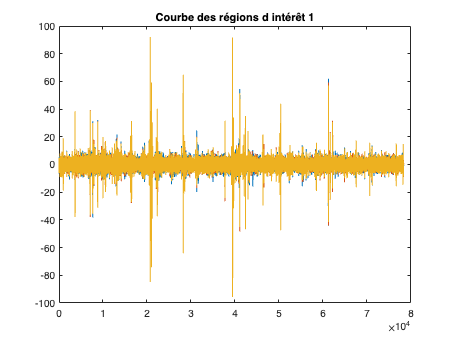


% extraire les signaux de chaque ROI


plot(roi3);
title('Courbe des régions d intérêt 1');

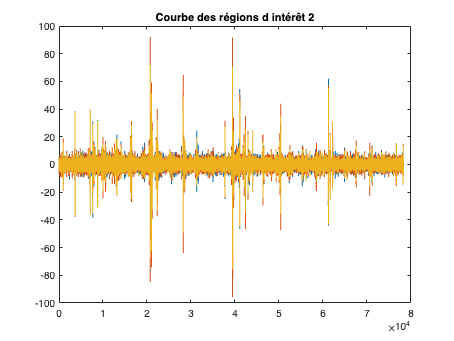

plot(roi4);
title('Courbe des régions d intérêt 2');


%% scalogramme %%



%% supp artefacts oculaires %%


%corr() 

%% supp artefacts musculaires %%

%cleanline()


% sélection des fenêtres d'échantillonnage

% analyse de fréquence (transformée en ondelettes)

% analyse synchronisation entre différentes régions du cerveau :
% utilisation corrélation croisée ou cohérence de phase

% analyse des caractéristiques : pics ondes cérébrales, pics puissance,
% latences etc

% classif (pas notre partie)